%{
ES115 Engineering Computer Applications 
Module 1 Project: Package Delivery Time Estimator

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 26, 2026

Purpose:
The purpose of this project is to model package delivery times based on travel 
distance using a linear equation. By implementing this in MATLAB, we can categorize 
delivery durations and visualize the impact of travel speed and fixed handling time 
on overall logistics efficiency.

Inputs:
- Distance Range (d): 0 to 40 miles
- Model Parameters: Travel rate (m) and handling time (b)

Outputs:
- Time Vector (T): Total estimated delivery times
- Delivery Table: Data summary with distance, time, and category labels
- Visualization: Plot of distance vs. time

Engineering Workflows:
- Predictive Modeling: Estimating system performance via linear functions
- Data Classification: Categorizing numerical data into qualitative groups
- Parameter Analysis: Interpreting physical meanings of the slope and intercept

MATLAB Tools:
- Vector Operations: Calculating values across the distance range
- table(): Structuring results for professional reporting
- Logical Indexing: Assigning categories based on time thresholds
- plot(): Graphing trends for visual data interpretation
%}


d = (0:1:40)';

m = 1.5; 
b = 15;  

T = m * d + b;

status = strings(size(d));
status(T < 30) = "Short";
status(T >= 30 & T <= 60) = "Medium";
status(T > 60) = "Long";

DeliveryTable = table(d, T, status, 'VariableNames', {'Distance_Miles', 'Time_Minutes', 'Category'});
disp(DeliveryTable);

    Distance_Miles    Time_Minutes    Category
    ______________    ____________    ________

           0                15        "Short" 
           1              16.5        "Short" 
           2                18        "Short" 
           3              19.5        "Short" 
           4                21        "Short" 
           5              22.5        "Short" 
           6                24        "Short" 
           7              25.5        "Short" 
           8                27        "Short" 
           9              28.5        "Short" 
          10                30        "Medium"
          11              31.5        "Medium"
          12                33        "Medium"
          13              34.5        "Medium"
          14                36        "Medium"
          15              37.5        "Medium"
          16                39        "Medium"
    

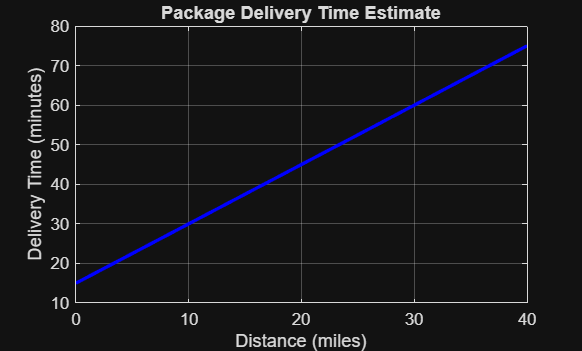


figure;
plot(d, T, 'b-', 'LineWidth', 2);
grid on;
xlabel('Distance (miles)');
ylabel('Delivery Time (minutes)');
title('Package Delivery Time Estimate');


fprintf('Slope (m = %.1f): Represents travel time per mile.\n', m);

Slope (m = 1.5): Represents travel time per mile.


fprintf('Intercept (b = %d): Represents the fixed handling time.\n', b);

Intercept (b = 15): Represents the fixed handling time.
